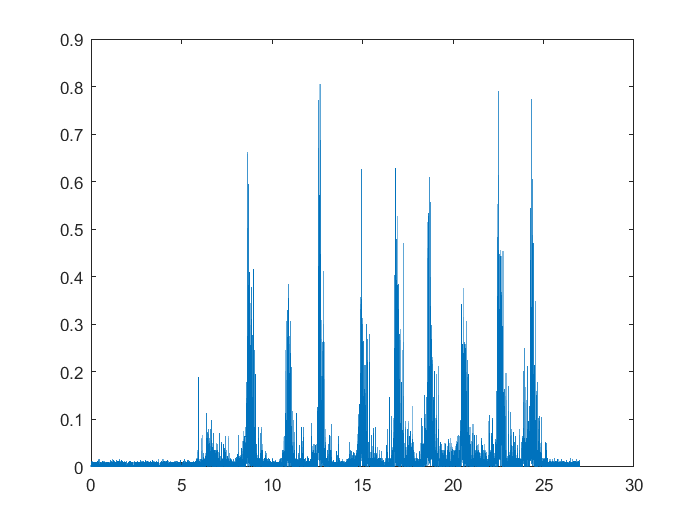

clear;
clc;

info= edfinfo('measurement/test/test_close.edf');
signal= edfread('measurement/test/test_close.edf', 'SelectedSignals','EMGBITREV');
fs = info.NumSamples/seconds(info.DataRecordDuration);
data_carray= table2array(signal);
data= vertcat(data_carray{:});

t= 0: 1/fs: (length(data)-1)*(1/fs);
L= length(data);
f= (0:L/2)*(fs/L);

figure()
plot(t,abs(data));

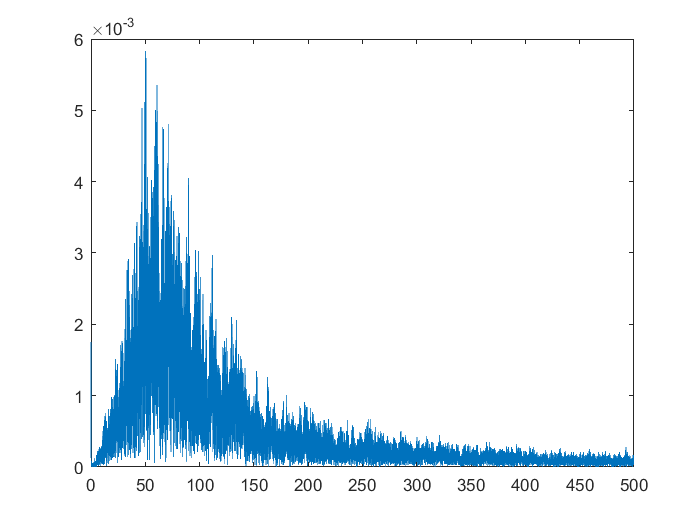


figure()
y= fft(data);
y= abs(y/L);
y= y(1: L/2+1);
plot(f, 2*y);

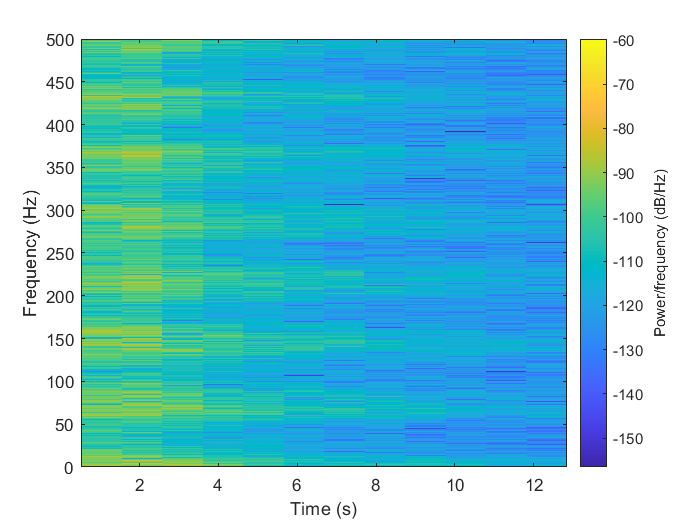

spectrogram(abs(y), 2048, 1020, 2048, fs, 'yaxis');

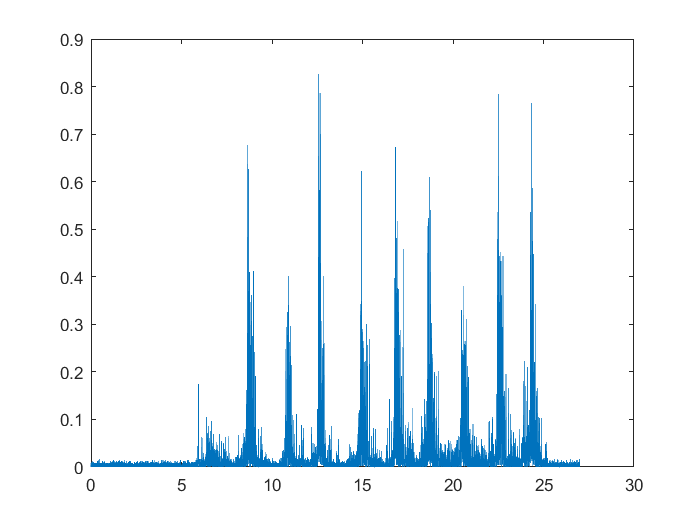


fnyq= fs/2;
fh= 20;
fl= 450;

[b, a]= butter(4, [fh, fl]/fnyq, "bandpass");

data= filtfilt(b, a, data);
rec_signal= abs(data);

plot(t, rec_signal);


% figure()
% y= fft(data);
% power = abs(data).^2;
% plot(f, power);

% figure()
% subplot(211);
% plot(t, power)
% plot(f, abs(y));
% subplot(212);
% spectrogram(abs(data), 2048, 1020, 2048, fs, 'yaxis');


% noise filtering
disp("Filtered noise.")

Filtered noise.




%filtrar, passsa baixo


%threshoulding and amplification